# Drop Down List Manager

This widget provides the user to edit and select from a list of names, and it does so within a compact space. You can easily add, remove, or rename items from the dropdown control using the connected buttons.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 350 150]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {30};

Create and configure the widget:

ddlWidget = wt.DropDownListManager(gridObj);
ddlWidget.ItemsChangedFcn = @(src,evt)disp(evt);

When you press the "add" button, this is the initial name for the new item:

ddlWidget.NewItemName = "<New Item>";

Add some items to the widget:

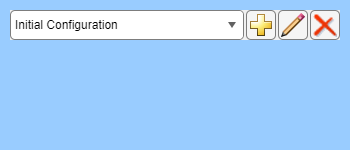

ddlWidget =   DropDownListManager with properties:

              Index: 1
              Value: "Initial Configuration"
              Items: ["Initial Configuration"    "Revision 1"    "Revision 2"]
          ItemsData: [1×0 double]
        AllowRemove: on
        AllowRename: on
    AllowItemRemove: [1 1 1]
    AllowItemRename: [1 1 1]
        NewItemName: "<New Item>"
       IsAddingItem: 0
     IsRenamingItem: 0
    ItemsChangedFcn: @(src,evt)disp(evt)
           Position: [11 111 330 30]

  Show all properties


ddlWidget.Items = [
    "Initial Configuration"
    "Revision 1"
    "Revision 2"
    ]

Optionally, you can disable removing or renaming individual items in the list. This triggers the corresponding buttons to be disabled while that item is selected

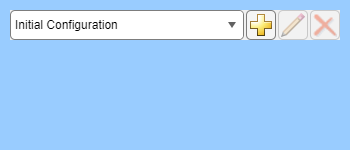

ddlWidget.AllowItemRemove(1) = false;
ddlWidget.AllowItemRename(1) = false;

Programmatically select a different item in the list:

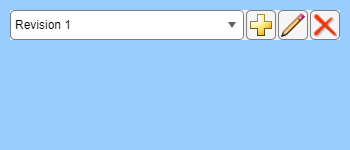

ddlWidget.Value = "Revision 1";

The remove and rename buttons are enabled by default, but you could set these properties to `FALSE` if you did not want them at all.

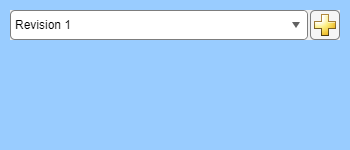

ddlWidget.AllowRemove = false;
ddlWidget.AllowRename = false;

*Copyright 2024-2025 The MathWorks, Inc.*